clear; clc; close all;

%Load signals
edfFilename = 'R1.edf';
[hdr, record1] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R2.edf';
[~, record2] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R3.edf';
[~, record3] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R4.edf';
[~, record4] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R5.edf';
[~, record5] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R6.edf';
[~, record6] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R7.edf';
[~, record7] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R8.edf';
[~, record8] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R9.edf';
[~, record9] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R10.edf';
[~, record10] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


## Get all segements of the signals LEFT EOG

EOGL_R1 = record1(6, 1:length(record1));
EOGL_R1 = EOGL_R1';
EOGL_R2 = record2(6, 1:length(record2)); 
EOGL_R2 = EOGL_R2';
EOGL_R3 = record3(6, 1:length(record3)); 
EOGL_R3 = EOGL_R3';
EOGL_R4 = record4(6, 1:length(record4)); 
EOGL_R4 = EOGL_R4';
EOGL_R5 = record5(6, 1:length(record5)); 
EOGL_R5 = EOGL_R5';
EOGL_R6 = record6(6, 1:length(record6)); 
EOGL_R6 = EOGL_R6';
EOGL_R7 = record7(6, 1:length(record7)); 
EOGL_R7 = EOGL_R7';
EOGL_R8 = record8(6, 1:length(record8)); 
EOGL_R8 = EOGL_R8';
EOGL_R9 = record9(6, 1:length(record9)); 
EOGL_R9 = EOGL_R9';
EOGL_R10 = record10(6, 1:length(record10)); 
EOGL_R10 = EOGL_R10';

## Get all segements of the signals RIGHT EOG

EOGR_R1 = record1(7, 1:length(record1));
EOGR_R1 = EOGR_R1';
EOGR_R2 = record2(7, 1:length(record2)); 
EOGR_R2 = EOGR_R2';
EOGR_R3 = record3(7, 1:length(record3)); 
EOGR_R3 = EOGR_R3';
EOGR_R4 = record4(7, 1:length(record4)); 
EOGR_R4 = EOGR_R4';
EOGR_R5 = record5(7, 1:length(record5)); 
EOGR_R5 = EOGR_R5';
EOGR_R6 = record6(7, 1:length(record6)); 
EOGR_R6 = EOGR_R6';
EOGR_R7 = record7(7, 1:length(record7)); 
EOGR_R7 = EOGR_R7';
EOGR_R8 = record8(7, 1:length(record8)); 
EOGR_R8 = EOGR_R8';
EOGR_R9 = record9(7, 1:length(record9)); 
EOGR_R9 = EOGR_R9';
EOGR_R10 = record10(7, 1:length(record10)); 
EOGR_R10 = EOGR_R10';



## Difference between left and right eye

% d1=EOGL_R1-EOGR_R1;
% d2=EOGL_R2-EOGR_R2;
% d3=EOGL_R3-EOGR_R3;
% d4=EOGL_R4-EOGR_R4;
% d5=EOGL_R5-EOGR_R5;

## Preprocessing

preprocessed_EOGL_R1 = preprocessEOG(EOGL_R1);
preprocessed_EOGL_R2 = preprocessEOG(EOGL_R2);
preprocessed_EOGL_R3 = preprocessEOG(EOGL_R3);
preprocessed_EOGL_R4 = preprocessEOG(EOGL_R4);
preprocessed_EOGL_R5 = preprocessEOG(EOGL_R5);
preprocessed_EOGL_R6 = preprocessEOG(EOGL_R6);
preprocessed_EOGL_R7 = preprocessEOG(EOGL_R7);
preprocessed_EOGL_R8 = preprocessEOG(EOGL_R8);
preprocessed_EOGL_R9 = preprocessEOG(EOGL_R9);
preprocessed_EOGL_R10 = preprocessEOG(EOGL_R10);

preprocessed_EOGR_R1 = preprocessEOG(EOGR_R1);
preprocessed_EOGR_R2 = preprocessEOG(EOGR_R2);
preprocessed_EOGR_R3 = preprocessEOG(EOGR_R3);
preprocessed_EOGR_R4 = preprocessEOG(EOGR_R4);
preprocessed_EOGR_R5 = preprocessEOG(EOGR_R5);
preprocessed_EOGR_R6 = preprocessEOG(EOGR_R6);
preprocessed_EOGR_R7 = preprocessEOG(EOGR_R7);
preprocessed_EOGR_R8 = preprocessEOG(EOGR_R8);
preprocessed_EOGR_R9 = preprocessEOG(EOGR_R9);
preprocessed_EOGR_R10 = preprocessEOG(EOGR_R10);

## Arrange dataset

epoch_EOGL_R1 = arrangeDataECG(preprocessed_EOGL_R1); 
epoch_EOGL_R2 = arrangeDataECG(preprocessed_EOGL_R2); 
epoch_EOGL_R3 = arrangeDataECG(preprocessed_EOGL_R3);
epoch_EOGL_R4 = arrangeDataECG(preprocessed_EOGL_R4);
epoch_EOGL_R5 = arrangeDataECG(preprocessed_EOGL_R5);
epoch_EOGL_R6 = arrangeDataECG(preprocessed_EOGL_R6);
epoch_EOGL_R7 = arrangeDataECG(preprocessed_EOGL_R7);
epoch_EOGL_R8 = arrangeDataECG(preprocessed_EOGL_R8);
epoch_EOGL_R9 = arrangeDataECG(preprocessed_EOGL_R9);
epoch_EOGL_R10 = arrangeDataECG(preprocessed_EOGL_R10);

%Number of samples for each recording
nSamplesL = [height(epoch_EOGL_R1);height(epoch_EOGL_R2);height(epoch_EOGL_R3);...
    height(epoch_EOGL_R4);height(epoch_EOGL_R5);height(epoch_EOGL_R6);height(epoch_EOGL_R7);height(epoch_EOGL_R8);height(epoch_EOGL_R9);height(epoch_EOGL_R10)];

epoch_EOGR_R1 = arrangeDataECG(preprocessed_EOGR_R1); 
epoch_EOGR_R2 = arrangeDataECG(preprocessed_EOGR_R2); 
epoch_EOGR_R3 = arrangeDataECG(preprocessed_EOGR_R3);
epoch_EOGR_R4 = arrangeDataECG(preprocessed_EOGR_R4);
epoch_EOGR_R5 = arrangeDataECG(preprocessed_EOGR_R5);
epoch_EOGR_R6 = arrangeDataECG(preprocessed_EOGR_R6);
epoch_EOGR_R7 = arrangeDataECG(preprocessed_EOGR_R7);
epoch_EOGR_R8 = arrangeDataECG(preprocessed_EOGR_R8);
epoch_EOGR_R9 = arrangeDataECG(preprocessed_EOGR_R9);
epoch_EOGR_R10 = arrangeDataECG(preprocessed_EOGR_R10);

%Number of samples for each recording
nSamplesR = [height(epoch_EOGR_R1);height(epoch_EOGR_R2);height(epoch_EOGR_R3);...
    height(epoch_EOGR_R4);height(epoch_EOGR_R5);height(epoch_EOGR_R6);height(epoch_EOGR_R7);height(epoch_EOGR_R8);height(epoch_EOGR_R9);height(epoch_EOGR_R10)];

## Create delta EOG

d1= epoch_EOGL_R1-epoch_EOGR_R1;
d2= epoch_EOGL_R2-epoch_EOGR_R2;
d3= epoch_EOGL_R3-epoch_EOGR_R3;
d4= epoch_EOGL_R4-epoch_EOGR_R4;
d5= epoch_EOGL_R5-epoch_EOGR_R5;
d6= epoch_EOGL_R6-epoch_EOGR_R6;
d7= epoch_EOGL_R7-epoch_EOGR_R7;
d8= epoch_EOGL_R8-epoch_EOGR_R8;
d9= epoch_EOGL_R9-epoch_EOGR_R9;
d10= epoch_EOGL_R10-epoch_EOGR_R10;

% blinkr1=blinkdet(EOGL_R1)

## Feature extraction (first left then right and then delta)

eogf_1 = extractFeaturesEOG2(epoch_EOGL_R1,EOGL_R1,epoch_EOGR_R1,EOGR_R1,d1);
eogf_2 = extractFeaturesEOG2(epoch_EOGL_R2,EOGL_R2,epoch_EOGR_R2,EOGR_R2,d2);
eogf_3 = extractFeaturesEOG2(epoch_EOGL_R3,EOGL_R3,epoch_EOGR_R3,EOGR_R3,d3);
eogf_4 = extractFeaturesEOG2(epoch_EOGL_R4,EOGL_R4,epoch_EOGR_R4,EOGR_R4,d4);
eogf_5 = extractFeaturesEOG2(epoch_EOGL_R5,EOGL_R5,epoch_EOGR_R5,EOGR_R5,d5);
eogf_6 = extractFeaturesEOG2(epoch_EOGL_R6,EOGL_R6,epoch_EOGR_R6,EOGR_R6,d6);
eogf_7 = extractFeaturesEOG2(epoch_EOGL_R7,EOGL_R7,epoch_EOGR_R7,EOGR_R7,d7);
eogf_8 = extractFeaturesEOG2(epoch_EOGL_R8,EOGL_R8,epoch_EOGR_R8,EOGR_R8,d8);
eogf_9 = extractFeaturesEOG2(epoch_EOGL_R9,EOGL_R9,epoch_EOGR_R9,EOGR_R9,d9);
eogf_10 = extractFeaturesEOG2(epoch_EOGL_R10,EOGL_R10,epoch_EOGR_R10,EOGR_R10,d10);

## Correlation coefficients

taskf('R1.xml', eogf_1, "EOG R1");
taskf('R2.xml', eogf_2, "EOG R2");
taskf('R3.xml', eogf_3, "EOG R3");
taskf('R4.xml', eogf_4, "EOG R4");
taskf('R5.xml', eogf_5, "EOG R5");
taskf('R6.xml', eogf_6, "EOG R6");
taskf('R7.xml', eogf_7, "EOG R7");
taskf('R8.xml', eogf_8, "EOG R8");
taskf('R9.xml', eogf_9, "EOG R9");
taskf('R10.xml', eogf_10, "EOG R10");

## SVM

allEOGfeatures = [eogf_1;eogf_2;eogf_3;eogf_4;eogf_5;eogf_6;eogf_7;eogf_8;eogf_9;eogf_10;]; %feature matrix
features_norm = normalize(allEOGfeatures);

%% Load and arrange stages
[~, stages_R1, ~, ~] = readXML('R1.xml');
[~, stages_R2, ~, ~] = readXML('R2.xml');
[~, stages_R3, ~, ~] = readXML('R3.xml');
[~, stages_R4, ~, ~] = readXML('R4.xml');
[~, stages_R5, ~, ~] = readXML('R5.xml');
[~, stages_R6, ~, ~] = readXML('R6.xml');
[~, stages_R7, ~, ~] = readXML('R7.xml');
[~, stages_R8, ~, ~] = readXML('R8.xml');
[~, stages_R9, ~, ~] = readXML('R9.xml');
[~, stages_R10, ~, ~] = readXML('R10.xml');

stages_R1 = reshape(stages_R1, 30, []);stages_R1 = stages_R1';
stages_R2 = reshape(stages_R2, 30, []);stages_R2 = stages_R2';
stages_R3 = reshape(stages_R3, 30, []);stages_R3 = stages_R3';
stages_R4 = reshape(stages_R4, 30, []);stages_R4 = stages_R4';
stages_R5 = reshape(stages_R5, 30, []);stages_R5 = stages_R5';
stages_R6 = reshape(stages_R6, 30, []);stages_R6 = stages_R6';
stages_R7 = reshape(stages_R7, 30, []);stages_R7 = stages_R7';
stages_R8 = reshape(stages_R8, 30, []);stages_R8 = stages_R8';
stages_R9 = reshape(stages_R9, 30, []);stages_R9 = stages_R9';
stages_R10 = reshape(stages_R10, 30, []);stages_R10 = stages_R10';

stages = [stages_R1; stages_R2; stages_R3; stages_R4; stages_R5;...
    stages_R6; stages_R7; stages_R8; stages_R9; stages_R10];

%% Approach 1: Create SVM model (one for each record)
[knownStages1, predictedStages1, testingData] = SVMmodelEOG(features_norm,...
    stages, nSamplesL, 'polynomial', 'FINAL_SVM_result_EEG.xlsx');

%% Approach 2: Create SVM model 
[knownStages2, predictedStages2] = new_SVMmodeEOG(features_norm,...
    stages, 'polynomial', 'FINAL_generic_SVM_result_EEG.xlsx');

%% Calculate confusion matrix for approach 1
%Get predictions for each recording
R1_prediction = predictedStages1(1:length(nonzeros(testingData(:,1))), 1); 
R2_prediction = predictedStages1(1:length(nonzeros(testingData(:,2))), 2); 
R3_prediction = predictedStages1(1:length(nonzeros(testingData(:,3))), 3); 
R4_prediction = predictedStages1(1:length(nonzeros(testingData(:,4))), 4);
R5_prediction = predictedStages1(1:length(nonzeros(testingData(:,5))), 5);
R6_prediction = predictedStages1(1:length(nonzeros(testingData(:,6))), 6); 
R7_prediction = predictedStages1(1:length(nonzeros(testingData(:,7))), 7); 
R8_prediction = predictedStages1(1:length(nonzeros(testingData(:,8))), 8); 
R9_prediction = predictedStages1(1:length(nonzeros(testingData(:,9))), 9);
R10_prediction = predictedStages1(1:length(nonzeros(testingData(:,10))), 10);


confusionMatrix(knownStages1, 1, R1_prediction)
confusionMatrix(knownStages1, 2, R2_prediction)
confusionMatrix(knownStages1, 3, R3_prediction)
confusionMatrix(knownStages1, 4, R4_prediction)
confusionMatrix(knownStages1, 5, R5_prediction)
confusionMatrix(knownStages1, 6, R6_prediction)
confusionMatrix(knownStages1, 7, R7_prediction)
confusionMatrix(knownStages1, 8, R8_prediction)
confusionMatrix(knownStages1, 9, R9_prediction)
confusionMatrix(knownStages1, 10, R10_prediction)

%% Calculate confusion matrix for approach 2
new_confusionMatrix(knownStages2, predictedStages2)

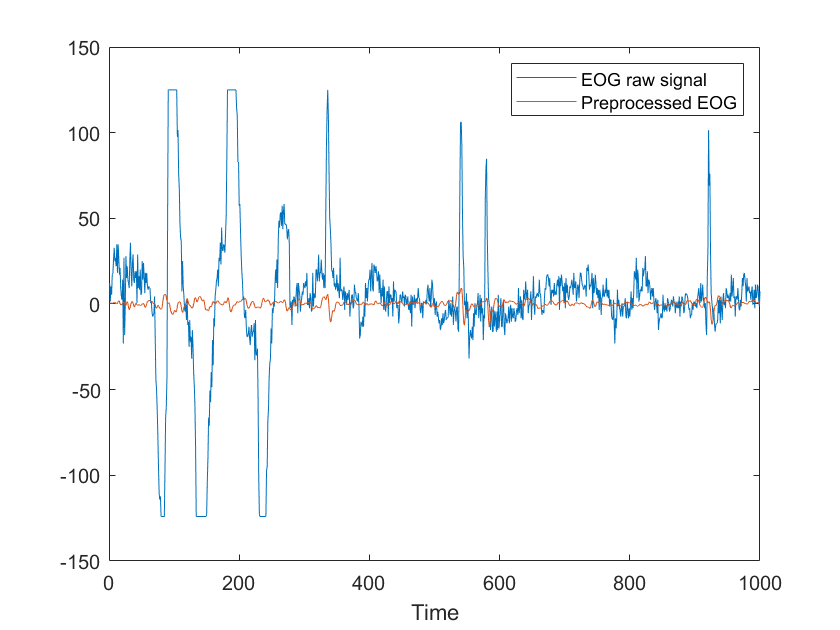

%% Plot for presentation
figure()
p1 = plot(EOGR_R1(1:1000));
hold on;
p2 = plot(preprocessed_EOGR_R1(1:1000));
xlabel('Time');
legend([p1 p2],{'EOG raw signal','Preprocessed EOG'});